## Plant definition


$$P_{\alpha } \left(s\right)=\frac{-0\ldotp 5125\left(s^2 +45\ldotp 915\right)}{s^2 \left(s^2 -36\ldotp 225\right)}$$


## Calculate the Feedback Controller

#### 我的版本

W = 400;

% unshaped plant
plant_num = -0.5125 * [1 0 45.915];
plant_denum = [1 0 -36.225 0 0]

plant_denum =     1.0000         0  -36.2250         0         0


P = tf(-0.5125*[1 0 45.915], [1 0 -36.225 0 0]);

% compute C2_hat using shaped plant data
C2_hat = TwoDOFFeedbackTuningFunction(W * (-0.5125*[1 0 45.915]), [1 0 -36.225 0 0]);

谱分解无明显误差



% absorb W
C2 = 1/W * C2_hat;

% loop (feedback only)
S = feedback(1, minreal(P*C2_hat));

% IMPORTANT: do NOT overwrite C2 afterwards
C1 = TwoDOFtuningFunction(plant_num, plant_denum, C2);
G = minreal((P*C1)/(1 + P*C2));

% Stability checks
isstable(S), pole(S);

ans = logical
   0


isstable(G), pole(G);

ans = logical
   1


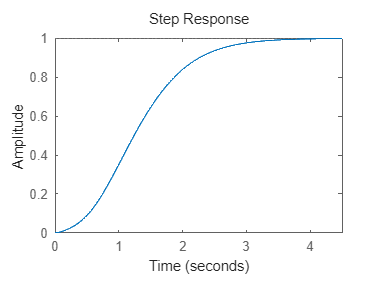

%step(G);
step(G);